# Polyphase Channelizer Model Simulation

This function simulates the MATLAB model of a polyphase channelizer to run on Versal devices.

The channelizer consists of a circular input buffer, a polyphase filter, a cyclic shift buffer, an IFFT (implemented as a DFT) operation, and an output buffer. The channelizer signal flow is depicted below:

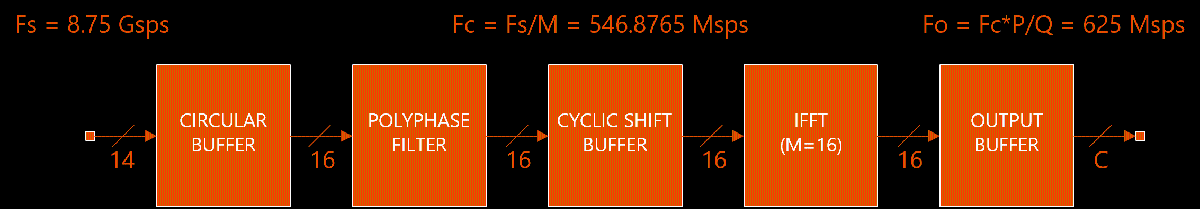

This design uses the following parameters:

- Fs = 8.75 Gsps

- M = 16 channels

- Oversampling ratio P/Q = 8 / 7.

- Each channel has Fc = Fs/M = 546.8765 Msps

- Output rate Fo = Fc * P/Q = 625 Msps

- SSR = 8

The parameters are initialized in the [channelizer_init](matlab:open('channelizer_init.mlx')) function.

function channelizer = channelizer_model(app, TT, FF)

## Create Input Signals

The input signals are modeled as band-limited white noise.

   sig_i = zeros(numel(app.chan_id),app.Nsamp);
   for mm = 1 : numel(app.chan_id)
     rng(mm);
     tmp = sqrt(0.5)*10^(0.05*-18)*complex(randn(1,app.Nsamp),randn(1,app.Nsamp));
     sig_i(mm,:) = filter(app.taps_sig,1,tmp);
   end
   sig_i = double(fi(sig_i,1,13,12,'RoundingMethod','Nearest','OverflowAction','Saturate'));

## Assign Signals to Channels and Perform Upconversion

The use of IFFT here matches 'tuning concept' for upconversion.

   ifft_i = zeros(app.Mchan,app.Nsamp);
   ifft_i(1+app.chan_id,:) = sig_i;
   ifft_o = zeros(app.Mchan,app.Nsamp);
   for ss = 1 : app.Nsamp
     tmp = ifft_i(:,ss);       
     ifft_o(:,ss) = app.Mchan*ifft(tmp);
   end

## Perform Polyphase Filtering at DAC

   tx_filt_o = zeros(app.Mchan,app.Nsamp);
   for mm = 1 : app.Mchan
     tx_filt_o(mm,:) = filter(app.taps_tx(mm,:),1,ifft_o(mm,:));
   end
   dac_o = reshape(tx_filt_o,1,[]); 

 Quantize the DAC output for H/W implementation:

   dac_o = double(fi(dac_o,TT,FF));

## Perform Polyphase Filtering at ADC

Now we assume P/Q oversampling at the RX channelizer:

   Nblock = numel(dac_o) / app.oversamp_ratio;
   data_i = reshape(dac_o,app.oversamp_ratio,[]);

Reverse order so newer samples are at lower indices.

   data_i = data_i(end:-1:1,:);

Initialize filter coefficients, filter state, and filter output.

   taps_rx = reshape(app.taps,app.Mchan,[]);
   state = zeros(app.Mchan,app.Ntaps);             % Filter has Ntaps per phase
   rx_filt_o = zeros(app.Mchan,Nblock);

## Input Circular Buffer and Polyphase Filter

### Circular Buffer

### Polyphase Filter

   for bb = 1 : Nblock

Load next inputs into state:

     state(1:app.oversamp_ratio,1) = data_i(:,bb);

Compute next filter output:

     rx_filt_o(:,bb) = sum(taps_rx .* state,2);

Update state using serpentine shift:

     tmp = circshift(reshape(state,1,[]),app.oversamp_ratio);
     tmp(1:app.oversamp_ratio) = 0;
     state = reshape(tmp,app.Mchan,[]);
   end

 Quantize the result and add delays to match AIE implementation:

   rx_filt_o = double(fi(rx_filt_o,TT,FF));
   rx_filt_o = cat(2,zeros(app.Mchan,16),rx_filt_o(:,1:end-16));

## Create Twiddle Matrix for IDFT

   M = 16;
   twiddle = zeros(M,M);
   omega = exp(1i*2*pi/M);   
   for rr = 1 : M
     for cc = 1 : M
       twiddle(rr,cc) = omega^((rr-1)*(cc-1));  
     end
   end

Take transpose since we formulate the diagrams this way:

   twiddle = transpose(twiddle);

Quantize the twiddle factors:

   twiddle = double(fi(twiddle,TT,'RoundingMethod','Convergent','OverflowAction','Saturate'));

## Cyclic Shift and RX IFFT

   state = 0;
   fft_o = zeros(app.Mchan,Nblock);
   all_o = zeros(app.Mchan,Nblock);
   for bb = 1 : Nblock

Compute shift amount:

     shift = state * app.Nshift;

Perform shift for next FFT input:

     fft_i = circshift(rx_filt_o(:,bb),shift);

Apply transform:

     all_o(:,bb) = transpose(fft_i) * twiddle;
     fft_o(:,bb) = app.Mchan * ifft( fft_i );

Update state:

     state = mod(state+1,app.Ncyclic);
   end

## Write Channelizer Input and Output Vectors

**Inputs: **There are 7 input streams. Need to send these '4 samples at a time' for each stream, interleaving streams after each set of 4.

    idx = 1;
    for ss = 1 : 2 : size(data_i,2)
      for xx = 1 : 7
            channelizer(xx).i(idx) = data_i(xx,ss+0);
            channelizer(xx).i(idx+1) = data_i(xx+7,ss+0);
            channelizer(xx).i(idx+2) = data_i(xx,ss+1);
            channelizer(xx).i(idx+3) = data_i(xx+7,ss+1);

      end
      idx = idx + 4;
    end

**Outputs:** There are 8 output streams. Data comes out on even streams first, then odd streams second as we go across the columns.

    all_o = double(fi(all_o,TT,FF));
    data = reshape(all_o,4,[]);
    channelizer(1).o = reshape(data(:,1:8:end),1,[]);
    channelizer(3).o = reshape(data(:,2:8:end),1,[]);
    channelizer(5).o = reshape(data(:,3:8:end),1,[]);
    channelizer(7).o = reshape(data(:,4:8:end),1,[]);
    channelizer(2).o = reshape(data(:,5:8:end),1,[]);
    channelizer(4).o = reshape(data(:,6:8:end),1,[]);
    channelizer(6).o = reshape(data(:,7:8:end),1,[]);
    channelizer(8).o = reshape(data(:,8:8:end),1,[]);

end